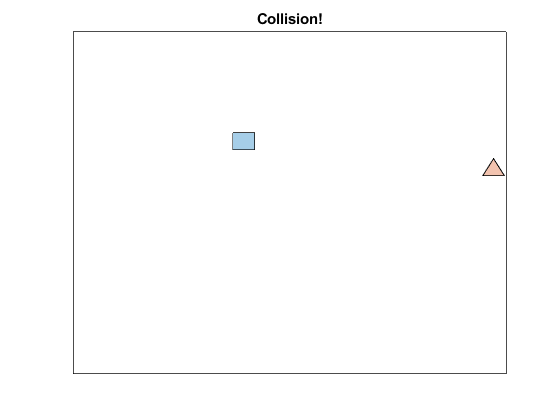

s = square;
t = triangle;
[v1,b1,v2,b2] = generateRandomV(2);
for i = linspace(0,2,60)
    s.polygon = translate(polyshape(s.xdata,s.ydata),v1*i-b1);
    t.polygon = translate(polyshape(t.xdata,t.ydata),v2*i+b2);
    collision = detectCollision(s,t);
    if collision == true
        title('Collision!')
        break
    elseif collision == false
        title('No collision')
    else
        title('Collision solved :)')
    end
    renderer([s.polygon,t.polygon])
end